% load experiment and replace units with new sorting
experiment.Units = sorted_from_phy('/lampllab/Data/Awake_AP2.5_ML4.0_A1/FVB/301121/986/kilosort/');
experiment.evokedEvents = experiment.getEvoked

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB108_986'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: []
            evokedEvents: [1×1 struct]
         conditionVector: []


% Find whisking epochs
[b,a] = butter(5,[0.1,100]/200,'bandpass');
mot_filt = filtfilt(b,a,double(motion_1))

mot_filt =   -11.5266  -13.2402  -20.7023  -31.2348  -34.5801  -20.8305    8.3597   32.8060   27.7435   -6.5711  -39.6928  -45.0514  -27.6104   -8.2030    5.6621   19.3213   31.1911   31.4273   19.7137    7.9979    1.0827   -9.1260  -22.9415  -25.6089  -11.2977    5.5803   13.9605   19.4699   24.6357   20.0482    5.2331   -5.4031   -6.4107   -8.9586  -17.2750  -18.2236   -2.5120   20.3517   35.5078   38.1200   30.2852   15.2823    0.6807   -3.2609    6.4027   22.1664   31.2997   21.8381   -5.2563  -27.3797


mot_filt = mot_filt/mean(mot_filt)

mot_filt = 1.0e+04 *

   -0.1395   -0.1602   -0.2506   -0.3780   -0.4185   -0.2521    0.1012    0.3970    0.3358   -0.0795   -0.4804   -0.5452   -0.3342   -0.0993    0.0685    0.2338    0.3775    0.3804    0.2386    0.0968    0.0131   -0.1104   -0.2777   -0.3099   -0.1367    0.0675    0.1690    0.2356    0.2982    0.2426    0.0633   -0.0654   -0.0776   -0.1084   -0.2091   -0.2206   -0.0304    0.2463    0.4297    0.4614    0.3665    0.1850    0.0082   -0.0395    0.0775    0.2683    0.3788    0.2643   -0.0636   -0.3314


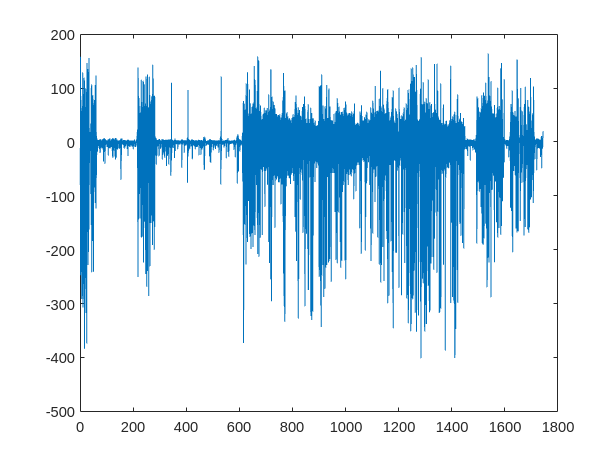

figure; plot([1:length(mot_filt)]/400,(mot_filt))

[whisk_envlope,~] = envelope(mot_filt);

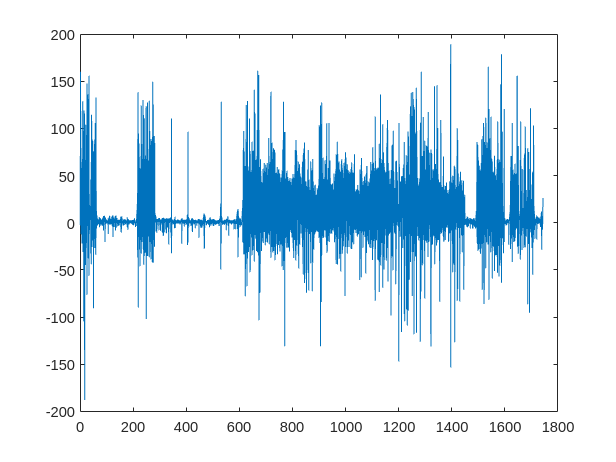

figure; plot([1:length(mot_filt)]/400,(whisk_envlope))

sigma = 0.2 * 400; % 200ms in terms of samples
smoothedEnv = imgaussfilt(whisk_envlope, sigma);

figure; plot([1:length(mot_filt)]/400,(smoothedEnv))
hold on
yline(1.5*prctile(smoothedEnv,15))

thershold = 2*prctile(smoothedEnv,15);
whiskingBinary = smoothedEnv > thershold;

cc = bwconncomp(whiskingBinary);

Fs = 400;

epochs = zeros(cc.NumObjects, 3); % [start, end, type]

for i = 1:cc.NumObjects
    epochs(i, 1) = cc.PixelIdxList{i}(1);   % start
    epochs(i, 2) = cc.PixelIdxList{i}(end); % end
    duration = (epochs(i, 2) - epochs(i, 1)) / Fs;
    
    if duration > 0.5 && duration <= 10
        epochs(i, 3) = 1; % Short epoch
    elseif duration > 10
        epochs(i, 3) = 2; % Long epoch
    end
end

figure;
plot(smoothedEnv, 'b'); % Original signal
hold on;

for i = 1:size(epochs, 1)
    startX = epochs(i, 1);
    endX = epochs(i, 2);
    
    if epochs(i, 3) == 1
        fill([startX, endX, endX, startX], [0, 0, 90, 90], 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    elseif epochs(i, 3) == 2
        fill([startX, endX, endX, startX], [0, 0, 90, 90], 'g', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    end
end

hold off;
xlabel('Sample Index');
ylabel('Amplitude');
title('Detected Whisking Epochs');

epochsEphys = [experiment.Cams.whisking.csv_aligned_frames(epochs(1:end-1,1:2)),epochs(1:end-1,3)]

epochsEphys =         -221     1966175           2
     1978482     1989589           0
     2259157     2300867           1
     2620952     2693520           1
     2712800     2748745           1
     2809168     2858243           1
     2859078     2881732           1
     3199851     3223107           1
     3236171     3248558           0
     3640295     3772148           1


experiment.Whisking.Raw = motion_1;
experiment.Whisking.smoothed = smoothedEnv;
experiment.Whisking.all = epochsEphys;
experiment.Whisking.short = epochsEphys(epochsEphys(:,3)==1,1:2)

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_1023'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [3635×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [-2.4235e-04 -2.4002e-04 -2.3768e-04 -2.3533e-04 -2.3298e-04 -2.3061e-04 -2.2824e-04 -2.2586e-04 -2.2347e-04 -2.2108e-04 -2.1869e-04 -2.1629e-04 -2.1389e-04 -2.1150e-04 -2.0909e-04 -2.0669e-04 -2.0429e-04 -2.0190e-04 … ]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
               

experiment.Whisking.long = epochsEphys(epochsEphys(:,3)==2,1:2)

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_1023'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [3635×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [-2.4235e-04 -2.4002e-04 -2.3768e-04 -2.3533e-04 -2.3298e-04 -2.3061e-04 -2.2824e-04 -2.2586e-04 -2.2347e-04 -2.2108e-04 -2.1869e-04 -2.1629e-04 -2.1389e-04 -2.1150e-04 -2.0909e-04 -2.0669e-04 -2.0429e-04 -2.0190e-04 … ]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
               

% Divide the neurons to conditions and cross with whisking epochs
experiment.conditionVector = experiment.getConVector(whiskVec)

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB110_600'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: []
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]


experiment.Units.perCondition = experiment.unitTimesCondition(whiskVec)

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB110_600'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: []
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]


experiment.Units.perCondition.FR = getFR(experiment)

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB110_600'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: []
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]


allUnits = [experiment.Units.perCondition.good.alum.FR;experiment.Units.perCondition.mua.alum.FR];
allUnits(:,2) = [experiment.Units.perCondition.good.muted.FR;experiment.Units.perCondition.mua.muted.FR];
allUnits(:,3) = [experiment.Units.perCondition.good.non.FR;experiment.Units.perCondition.mua.non.FR];

allUnits = allUnits./([experiment.Units.perCondition.FR.good,experiment.Units.perCondition.FR.mua]')

allUnits =     1.1040    0.9995    0.9925
    1.0264    0.9920    0.9854
    0.9910    1.0356    1.1166
    1.0717    1.0221    1.0351
    0.8496    0.9900    1.0387
    0.8694    1.0327    1.0722
    1.0975    0.8121    0.7861
    0.8715    1.1117    1.2617
    0.9242    0.9868    0.9281
    1.4168    0.9241    0.8857


experiment.Units.perCondition.allNorm = allUnits;

%save exp 
save('FVB108_986.mat','experiment')